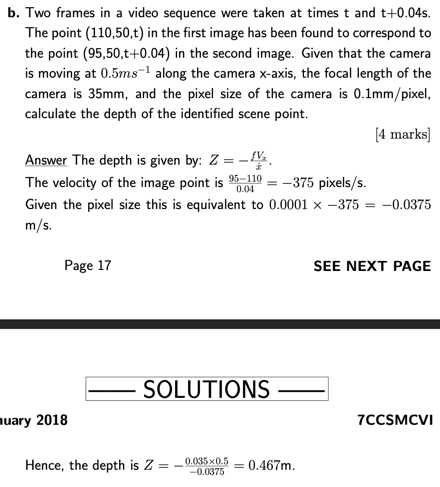

% 2017-2018, p17
first_point = [110, 50]

first_point =    110    50


second_point = [95, 50]

second_point =     95    50


focal_length = 0.035

focal_length = 0.0350

time = 0.04

time = 0.0400

cam_velocity = 0.5

cam_velocity = 0.5000

pixel_size = 0.1 * 100^-1

pixel_size = 1.0000e-03


img_velocity = (second_point(1) - first_point(1)) / time

img_velocity = -375

equivalent_pixel_size = pixel_size * img_velocity

equivalent_pixel_size = -0.3750

Z = - (focal_length * cam_velocity) / equivalent_pixel_size

Z = 0.0467

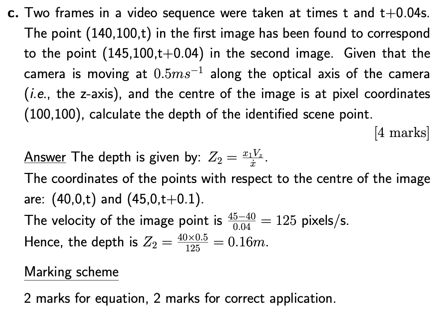

% 2017-2018, p18
first_point = [140, 100]

first_point =    140   100


second_point = [145, 100]

second_point =    145   100


center_point = [100, 100]

center_point =    100   100


time = 0.04

time = 0.0400

cam_velocity = 0.5

cam_velocity = 0.5000


% use x-coordinates
point_t = first_point - center_point;
point_t_1 = second_point - center_point;
img_velocity = (point_t_1(1) - point_t(1)) / time;
Z = (point_t(1) * cam_velocity) / img_velocity

Z = 0.1600

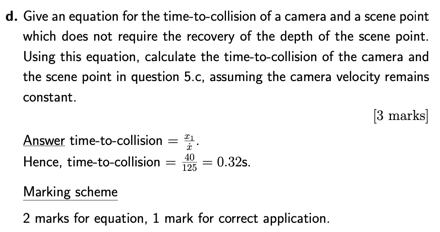

% 2017-2018, p18
time_to_collision = point_t(1) / img_velocity

time_to_collision = 0.3200

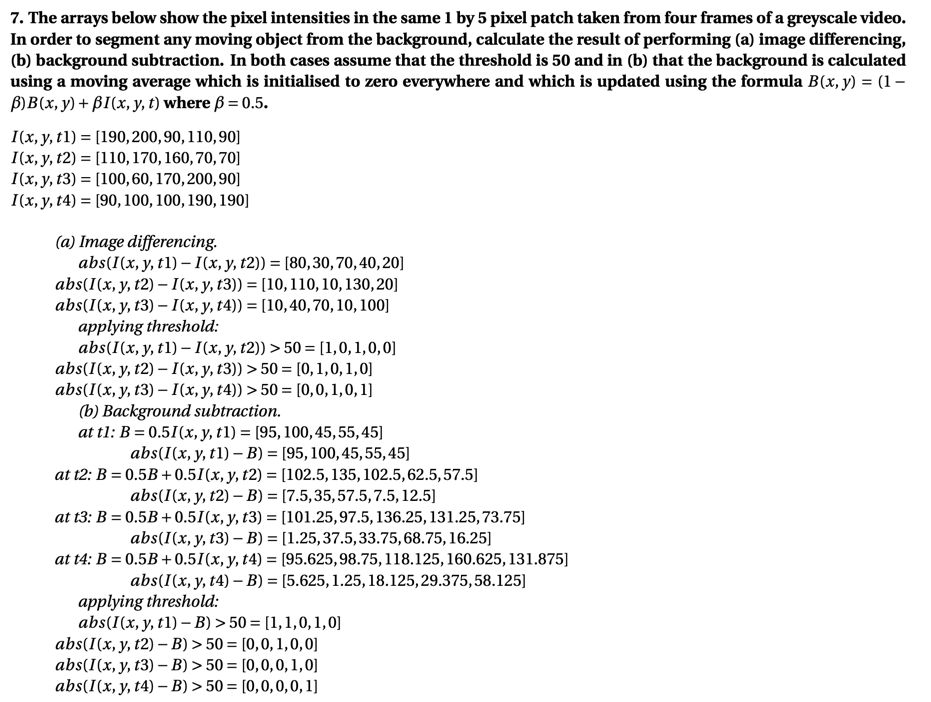

I_t1 = [190 200 90 110 90];
I_t2 = [110 170 160 70 70];
I_t3 = [100 60 170 200 90];
I_t4 = [90 100 100 190 190];
th = 50;
beta = 0.5;

% Image differencing
abs(I_t1 - I_t2) > th

ans = 1×5 logical array
   1   0   1   0   0


abs(I_t2 - I_t3) > th

ans = 1×5 logical array
   0   1   0   1   0


abs(I_t3 - I_t4) > th

ans = 1×5 logical array
   0   0   1   0   1



% Background subtraction
t1_B = background_subtraction(I_t1, 0, beta);
abs(I_t1 - t1_B) > th

ans = 1×5 logical array
   1   1   0   1   0



t2_B = background_subtraction(I_t2, t1_B, beta);
abs(I_t2 - t2_B) > th

ans = 1×5 logical array
   0   0   1   0   0



t3_B = background_subtraction(I_t3, t2_B, beta);
abs(I_t3 - t3_B) > th

ans = 1×5 logical array
   0   0   0   1   0



t4_B = background_subtraction(I_t4, t3_B, beta);
abs(I_t4 - t4_B) > th

ans = 1×5 logical array
   0   0   0   0   1


function out = background_subtraction(I, B, beta, th)
    out = (1-beta)*B + beta*(I);
%     out = abs(I - t_B);
end